# Discrete LQR strategy for Determining Optimal Inhibitor Dose Level Based on Mathematical Model of Tumor Growth Dynamics 

#### Optimal Control Project - Christian Brignone (1615574), Gioia Mancini (1659938)

clear all

lambda=0.192; 
b=5.85; 
d=0.00873; 
e=0.66;
r=1;
params_constant_u = {lambda,b,d,e};

Response of tumor volume and supporting vasculature volume without and under inhibitor doses of various constant levels

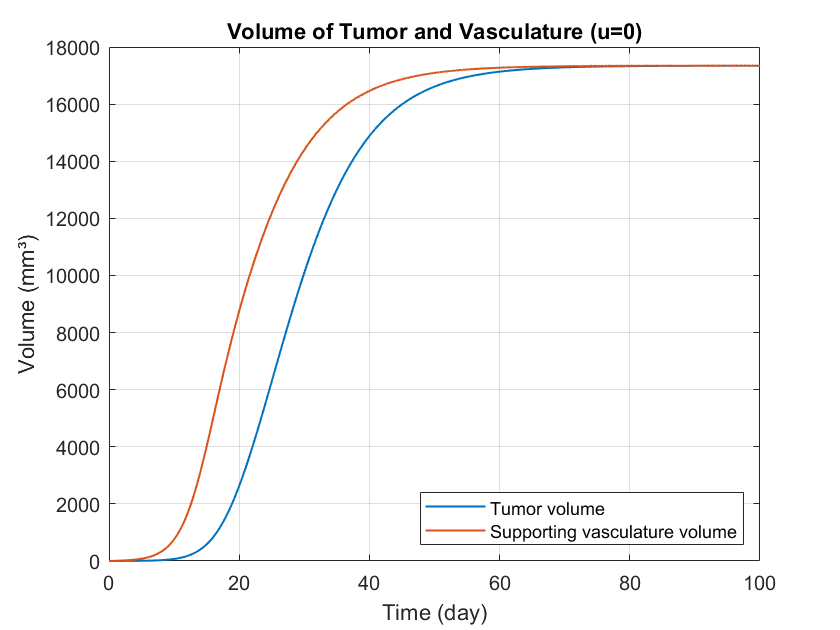

state_0_constant_u =[1; 1];
tspan_constant_u = [0:0.1:100];
plot_constant_inhibitor(0,params_constant_u,tspan_constant_u,state_0_constant_u,[0,18000])

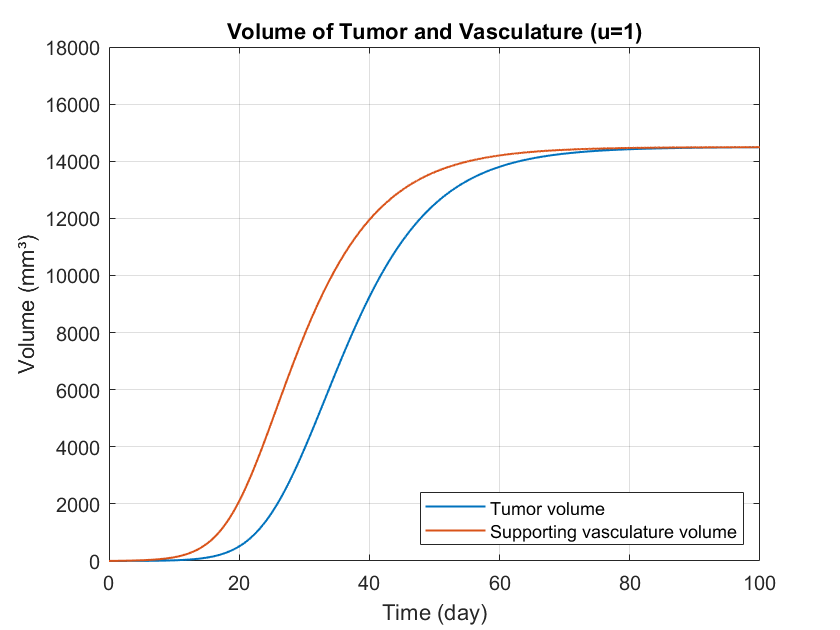

plot_constant_inhibitor(1,params_constant_u,tspan_constant_u,state_0_constant_u,[0,18000])

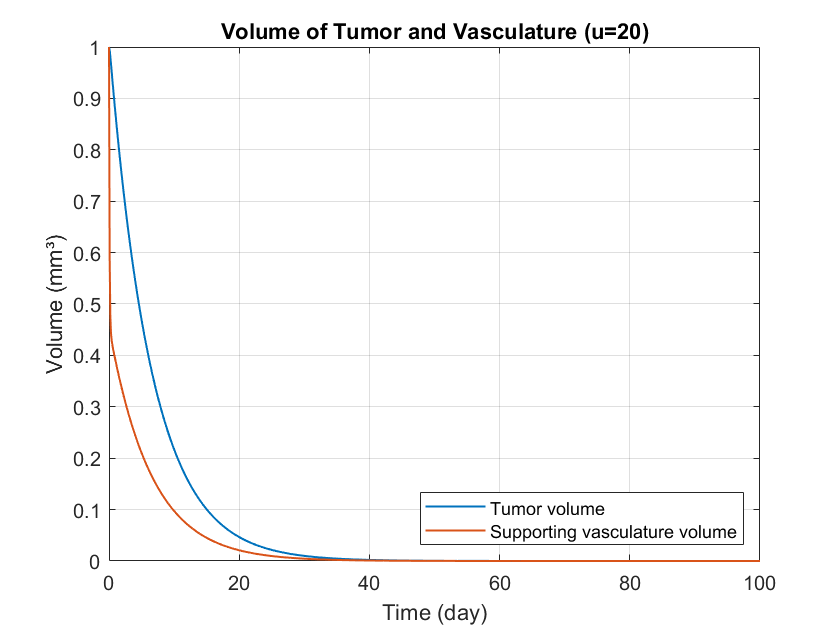

plot_constant_inhibitor(20,params_constant_u,tspan_constant_u,state_0_constant_u,[0,1])

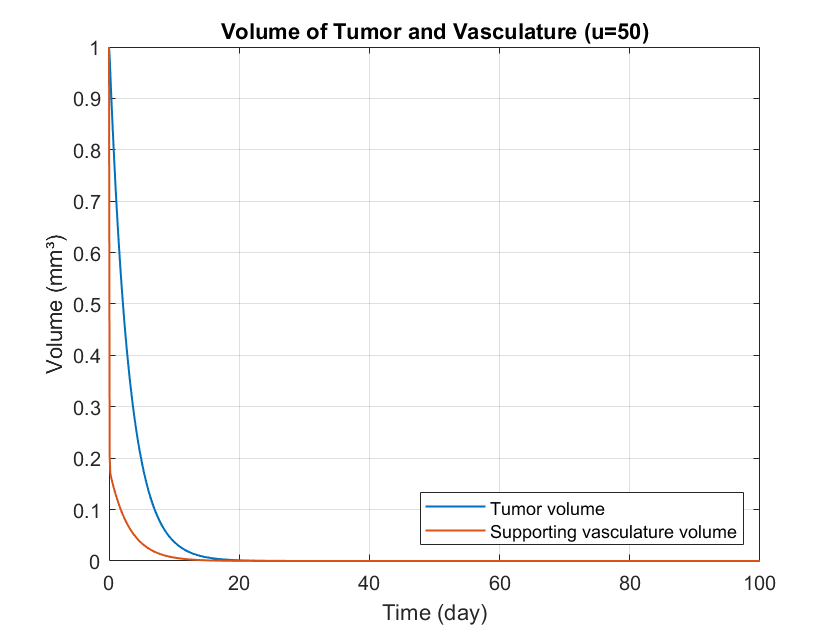

plot_constant_inhibitor(50,params_constant_u,tspan_constant_u,state_0_constant_u,[0,1])

Feedback linearized model in z coordinates:

A = [0 1; 0 0];
B = [0; 1];
C = [1 0];
D = 0;

Optimal discrete state-feedback design

discrete_time_system = c2d(ss(A,B,C,D),0.1)


discrete_time_system =
 
  A = 
        x1   x2
   x1    1  0.1
   x2    0    1
 
  B = 
          u1
   x1  0.005
   x2    0.1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.1 seconds
Discrete-time state-space model.



A_d=discrete_time_system.A;
B_d=discrete_time_system.B;
C_d=discrete_time_system.C;
Q=[1,0;0,0];
H=[1,0;0,0];
r=1;
state_0 =[2000; 8000];
tspan = [0:0.1:50];
lambda=0.192; b=5.85; d=0.00873; e=0.66;

Case R=1

K =      9.317451415091824e-01     1.365097169808200e+00


G =      9.317451415091825e-01


total_inhibitor_dose =      1.377649765946793e+04


days =      1.450000000000000e+01


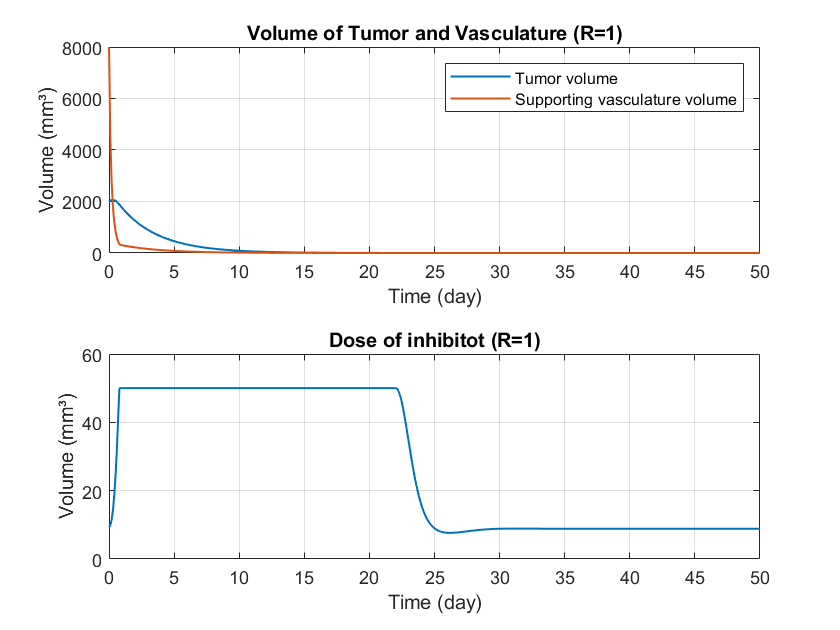

[states,u,t,total_inhibitor_dose,days_to_1perc]=tumor_growth_simulation(A_d, ...

                           B_d,C_d,Q,1,H,lambda,b,d,e,r,tspan,state_0,true,true);

Case R=10

K =      3.039009467385543e-01     7.796165038749431e-01


G =      3.039009467385543e-01


total_inhibitor_dose =      1.374866791775597e+04


days =      1.560000000000000e+01


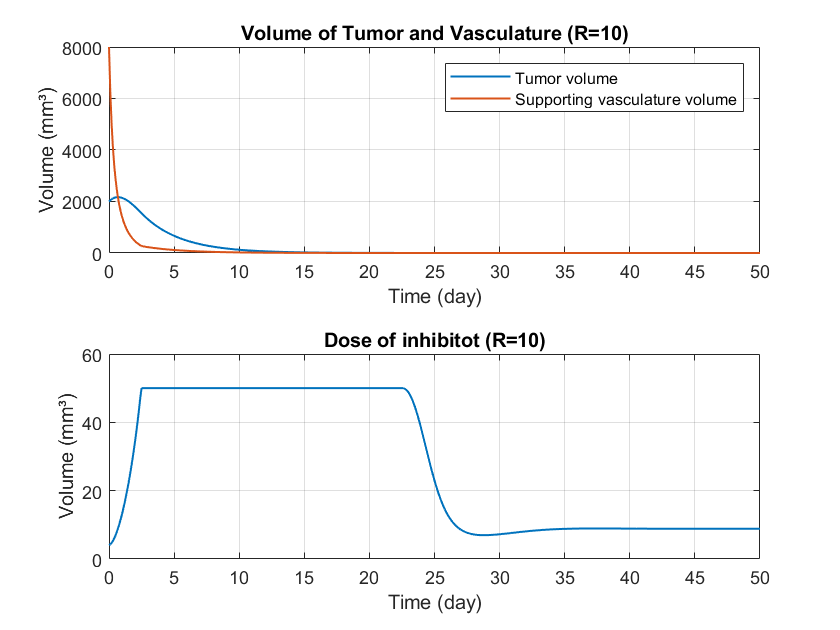

[states,u,t,total_inhibitor_dose,days_to_1perc]=tumor_growth_simulation(A_d, ...

                         B_d,C_d,Q,10,H,lambda,b,d,e,r,tspan,state_0,true,true);

Case R=100

K =      9.778879137876374e-02     4.422415403734525e-01


G =      9.778879137876374e-02


total_inhibitor_dose =      1.385700361523058e+04


days =      1.890000000000000e+01


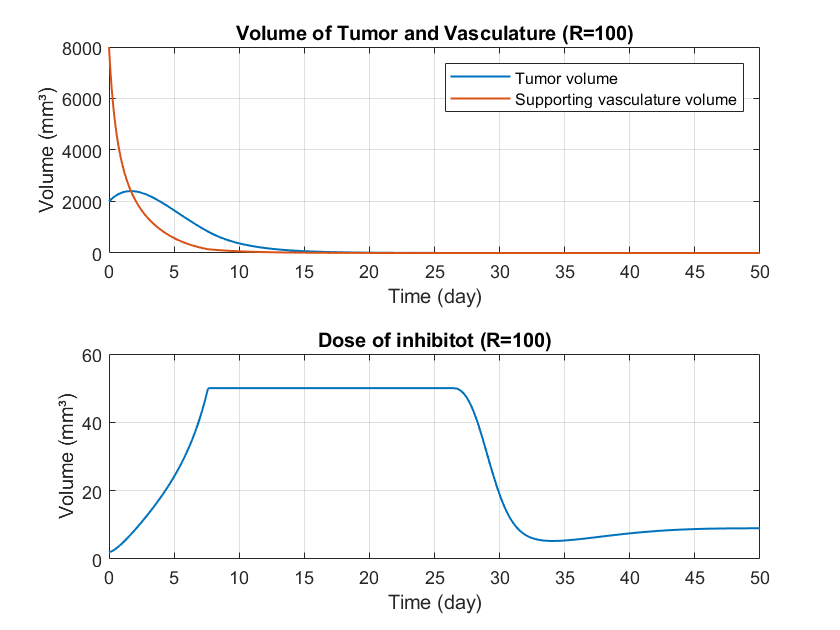

[states,u,t,total_inhibitor_dose,days_to_1perc]=tumor_growth_simulation(A_d, ...

                        B_d,C_d,Q,100,H,lambda,b,d,e,r,tspan,state_0,true,true);

Case R=1000

K =      3.122763054129877e-02     2.499104993415736e-01


G =      3.122763054129877e-02


total_inhibitor_dose =      1.447128225611787e+04


days =      2.720000000000000e+01


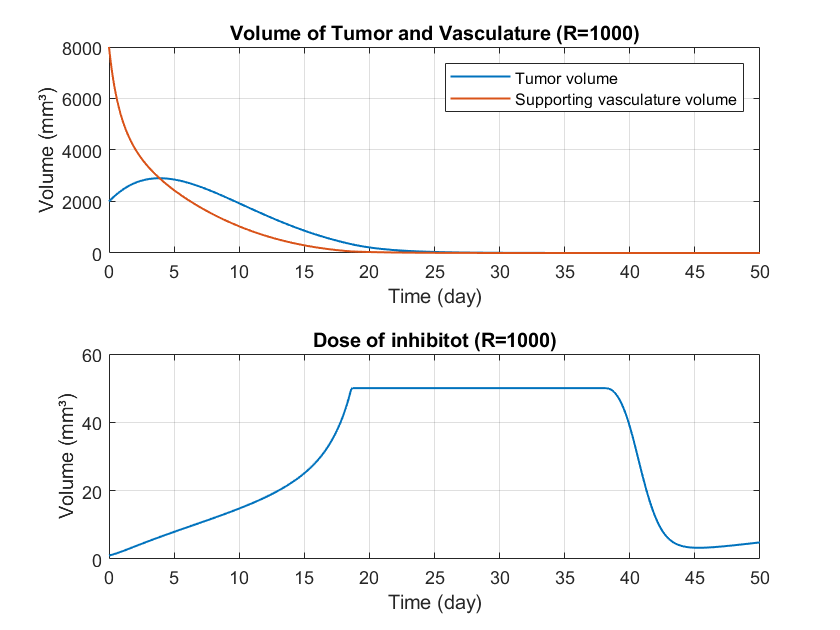

[states,u,t,total_inhibitor_dose,days_to_1perc]=tumor_growth_simulation(A_d, ...

                       B_d,C_d,Q,1000,H,lambda,b,d,e,r,tspan,state_0,true,true);
R_list=[2:99];%[1,10:10:100];
total_inhibitor_doses=zeros(size(R_list));

time_lenghts=zeros(size(R_list));
for i=1:size(R_list,2)
    [states,u,t,total_inhibitor_dose,days]=tumor_growth_simulation(A_d, ...
                    B_d,C_d,Q,R_list(i),H,lambda,b,d,e,r,tspan,state_0,false,false);
    total_inhibitor_doses(i)=total_inhibitor_dose;
    days_to_1perc_list(i)=days;
end
total_inhibitor_doses

total_inhibitor_doses =      1.376456231560103e+04     1.375790273189442e+04     1.375401769631372e+04     1.375192850715124e+04     1.375118842676259e+04     1.374941300539053e+04     1.374971290653771e+04     1.374837972764748e+04     1.374866791775597e+04     1.374972163576378e+04     1.374999881206443e+04     1.375027907628122e+04     1.375025435719383e+04     1.375148394842037e+04     1.375233670024521e+04     1.375313700208432e+04     1.375480438152618e+04     1.375607793658690e+04     1.375726371480094e+04     1.375830539764650e+04     1.376065320042415e+04     1.376106950991415e+04     1.376215885317498e+04     1.376356980168973e+04     1.376499108194990e+04     1.376594119883109e+04     1.376841492213566e+04     1.376914733782829e+04     1.377087275346817e+04     1.377230842991726e+04     1.377319909017439e+04     1.377458767249536e+04     1.377596280345086e+04     1.377748074926015e+04     1.377937428127854e+04     1.378114798034272e+04     1.378169233286667e+04     1.3783299

days_to_1perc_list

days_to_1perc_list =      1.470000000000000e+01     1.490000000000000e+01     1.500000000000000e+01     1.520000000000000e+01     1.530000000000000e+01     1.540000000000000e+01     1.550000000000000e+01     1.550000000000000e+01     1.560000000000000e+01     1.570000000000000e+01     1.580000000000000e+01     1.580000000000000e+01     1.590000000000000e+01     1.600000000000000e+01     1.600000000000000e+01     1.610000000000000e+01     1.620000000000000e+01     1.620000000000000e+01     1.630000000000000e+01     1.630000000000000e+01     1.640000000000000e+01     1.640000000000000e+01     1.650000000000000e+01     1.650000000000000e+01     1.660000000000000e+01     1.660000000000000e+01     1.670000000000000e+01     1.670000000000000e+01     1.680000000000000e+01     1.680000000000000e+01     1.690000000000000e+01     1.690000000000000e+01     1.690000000000000e+01     1.700000000000000e+01     1.700000000000000e+01     1.710000000000000e+01     1.710000000000000e+01     1.7100000000

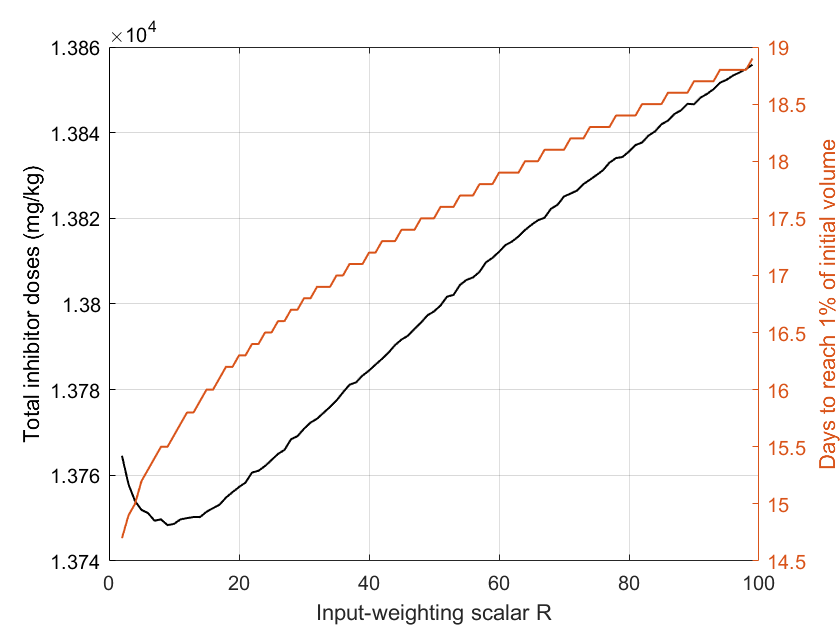

[min_tid, idx_min_tid]=min(total_inhibitor_doses);


plot_total_inhibitor_doses(total_inhibitor_doses,R_list,days_to_1perc_list)

disp(['The minimum total inhibitor dose is ',num2str(min_tid), ...
              ' for a choice of R=',num2str(R_list(idx_min_tid))])

The minimum total inhibitor dose is 13748.3797 for a choice of R=9


Functions:

Dynamical Model

function tumorModelstate = tumorModel(t,state,params)
tumorModelstate = [
    -params{1}*state(1)*log(state(1)/state(2));
    params{2}*state(1)-params{3}*state(1)^(2/3)*state(2)-params{4}*state(2)* ...
            control_u(state(1),state(2),params{1},params{2},params{3}, ...
            params{4}, params{5},params{6},params{7},params{8},params{9})
    ];
end

function tumorModelstate_constant_u = tumorModel_constant_u(t,state,params,u)
tumorModelstate_constant_u = [
    -params{1}*state(1)*log(state(1)/state(2));
    params{2}*state(1)-params{3}*state(1)^(2/3)*state(2)-params{4}*state(2)*u
    ];
end

Discrete LQR with set-point 

function [K,G]=dlqr_sp(A_d,B_d,C,Q,R,H)
    S_i=H;
    K_i=[1,1];
    N=0;
    buffSize = 20;
    circBuff = zeros(1,buffSize);
    while abs(sum(K_i*(buffSize/2))-sum(circBuff))>10^-7
        N=N+10;
        for i=N-1:-1:0
            S_i=A_d'*(S_i-S_i*B_d*1/(B_d'*S_i*B_d+R)*B_d'*S_i)*A_d+Q;
            circBuff = [circBuff(3:end),K_i];
            K_i=(1/(R))*B_d'/(A_d')*(S_i-Q);
        end
    end
    K=K_i;
    G=1/(C/(eye(2)-A_d+B_d*K)*B_d);%G=1/(C/(B_d*K-A_d)*B_d)
end

Control Function

function u=control_u(x1,x2,lambda,b,d,e,K,G,r,A_d,B_d)
beta = -e*lambda*x1;
alpha = (lambda*log(x1/x2)+lambda)*lambda*x1*log(x1/x2) ...
                    +lambda*(x1/x2)*(b*x1-d*(x1^(2/3))*x2);

z1 = x1;
z2 = -lambda*x1*log(x1/x2);
z=[z1;z2];
I2=eye(2);
gamma=inv(I2+B_d*K);
A_new=gamma*A_d;
B_new=gamma*B_d*G;
z_new=A_new*z+B_new*r;

v=-K*z_new+G*r;
u=(v-alpha)/beta;
if u<0
    u=0;
end
if u>50
    u=50; %saturation
end
end

System integration

function [states,u,t,total_inhibitor_dose,days]=tumor_growth_simulation(A_d, ...
                                 B_d,C_d,Q,R,H,lambda,b,d,e,r,tspan,state_0,plot,verbose)
    
    [K,G]=dlqr_sp(A_d,B_d,C_d,Q,R,H);
    index_days_to_1perc=tspan(end);
    first_time=true;
    params = {lambda,b,d,e,K,G,r,A_d,B_d}; 
    [t,states]=ode45(@(t,state)tumorModel(t,state,params),tspan,state_0);
    u=zeros(size(t'));
    for i=1:size(states,1)
        u(i)=control_u(states(i,1),states(i,2),params{1},params{2},params{3}, ...
                    params{4},params{5},params{6},params{7},params{8},params{9});
        if states(i)<=(state_0(1)/100) && first_time
            index_days_to_1perc=i;
            first_time=false;
        end
    end
    total_inhibitor_dose=sum(u);
    days=t(index_days_to_1perc);
    if verbose
        K
        G
        total_inhibitor_dose
        days
    end
    if plot
        plot_inhibitor(t,states,u,R)
    end
end

Plot functions


function plot_inhibitor(t,states,u,R)
    figure
    tiledlayout(2,1)
    % Top plot
    ax1 = nexttile;
    plot(ax1,t,states,'LineWidth',1)
    title(ax1,['Volume of Tumor and Vasculature (R=',num2str(R),')'])
    ylabel(ax1,'Volume (mm³)')
    xlabel(ax1,'Time (day)')
    legend('Tumor volume','Supporting vasculature volume')
    grid on
    % Bottom plot
    ax2 = nexttile;
    plot(ax2,t,u,'LineWidth',1)
    title(ax2,['Dose of inhibitot (R=',num2str(R),')'])
    ylabel(ax2,'Inhibitor dose (mg/kg)')
    ylabel(ax2,'Volume (mm³)')
    xlabel(ax2,'Time (day)')
    ylim([0,60])
    grid on

end

function plot_total_inhibitor_doses(total_inhibitor_doses,R_list,days_to_1perc_list)
    figure
 
    %xx=linspace(R_list(1),R_list(end),1000);
    %yy=interp1(R_list,total_inhibitor_doses,xx,'spline');  
    
    %days_to_1perc_list_yy=interp1(R_list,xx,'spline');
    plot(R_list,total_inhibitor_doses,'LineWidth',1)
    
    ylabel('Total inhibitor doses (mg/kg)')
    xlabel('Input-weighting scalar R')
    grid on
    yyaxis right
    plot(R_list,days_to_1perc_list,'LineWidth',1)
    ylabel('Days to reach 1% of initial volume')
end

function plot_constant_inhibitor(constant_u,params_constant_u, ...
                        tspan_constant_u,state_0_constant_u,y_lim)
    [t_constant_u,states_constant_u]=ode45(@(t_constant_u, ...
              state_constant_u)tumorModel_constant_u(t_constant_u,state_constant_u, ...
              params_constant_u,constant_u),tspan_constant_u,state_0_constant_u);
    figure
    plot(t_constant_u,real(states_constant_u),'LineWidth',1)
    xlabel('Time (day)')
    ylabel('Volume (mm³)')
    legend({'Tumor volume','Supporting vasculature volume'},'Location','southeast')
    grid on
    title(['Volume of Tumor and Vasculature (u=',num2str(constant_u),')'])
    ylim(y_lim)
end